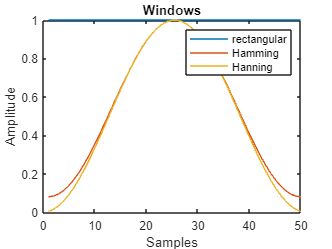

%problem1 part 1
L0=50;
x1=rectwin(L0);
plot(x1)
hold on
title('rectangular window');
xlabel('samples');
ylabel('amplitude');
x2 = hamming(L0);
plot(x2)
title('hamming window');
xlabel('samples');
ylabel('amplitude')
x3 = hanning(L0);
plot(x3)
title('hanning window');
xlabel('samples');
ylabel('amplitude')
title("Windows")
xlabel("Samples")
ylabel("Amplitude")
legend("rectangular","Hamming","Hanning")
hold off

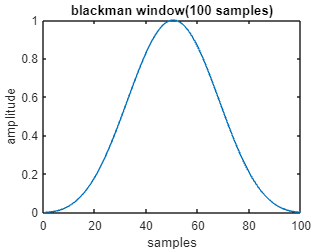


%problem 1 part 2
alpha=1+mod(163,3);
L1=100;
L2=200;
b1=blackman(100);
plot(b1)
title('blackman window(100 samples)');
xlabel('samples');
ylabel('amplitude')

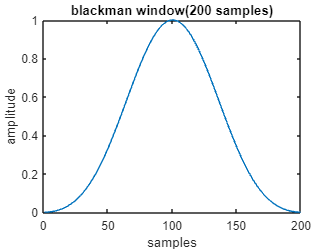

b2=blackman(200);
plot(b2)
title('blackman window(200 samples)');
xlabel('samples');
ylabel('amplitude')

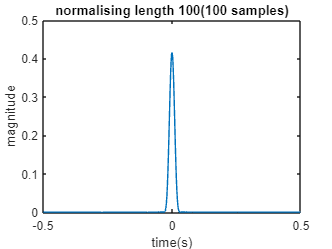

Fs = 1000;                              
T = 1/Fs;                    
L = 1024;             
t = (-L/2:L/2-1)./L;
%100samples
%normalising length=100
B11=blackman(L1);
y11=abs(fftshift(fft(B11,1024)))/100;      
plot(t,y11)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 100(100 samples)');

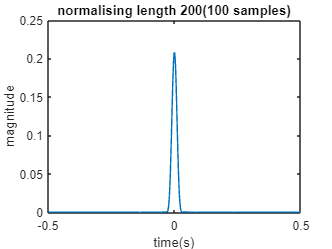

%normalising length=200
B12=blackman(L1);
y12=abs(fftshift(fft(B12,1024)))/200;
plot(t,y12)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 200(100 samples)');

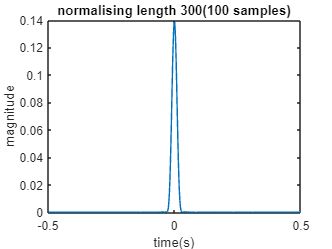

%normalising length 300
B13=blackman(L1);
y13=abs(fftshift(fft(B13,1024)))/300;
plot(t,y13)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 300(100 samples)');

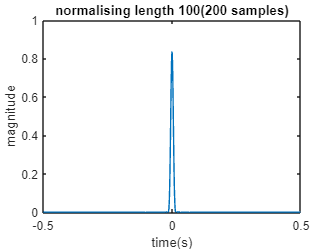


%200 samples
%normalising length=100
B21=blackman(L2);
y21=abs(fftshift(fft(B21,1024)))/100;      
plot(t,y21)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 100(200 samples)');

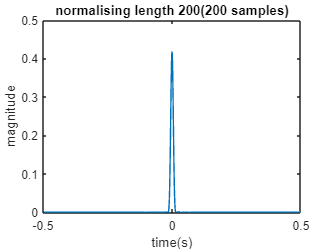

%normalising length=200
B22=blackman(L2);
y22=abs(fftshift(fft(B22,1024)))/200;      
plot(t,y22)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 200(200 samples)');

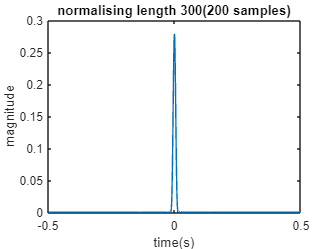

%normalising length=300
B23=blackman(L2);
y23=abs(fftshift(fft(B23,1024)))/300;      
plot(t,y23)
xlabel('time(s)');
ylabel('magnitude');
title('normalising length 300(200 samples)');

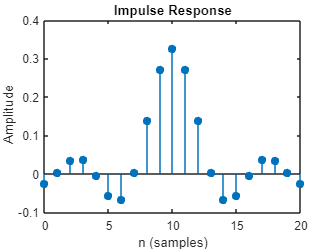




%question 2 
w1=rectwin(21);
a=fir1(20,0.33,'low',w1);
impz(a)

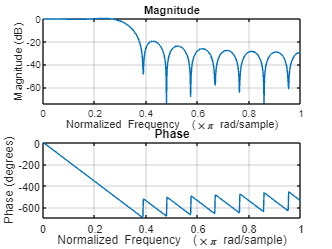

freqz(a)

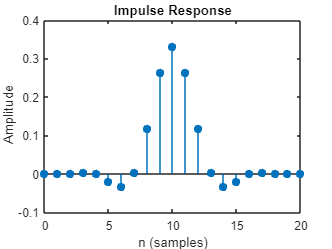


w2=blackman(21);
a1=fir1(20,0.33,'low',w2);
impz(a1)

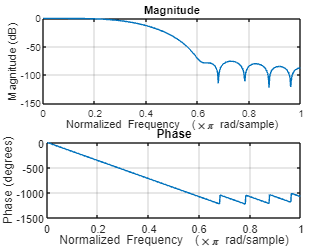

freqz(a1)

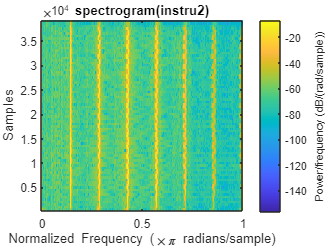


%problem 3
[y,Fs1]=audioread("C:\Users\vishn\OneDrive\Desktop\instru2.wav");
N=1000;
spectrogram(y,hamming(N))
title('spectrogram(instru2)');

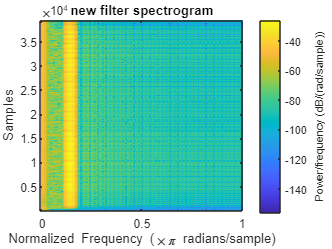

B4=fir1(99,1800/Fs1,'low',hamming(100));
y4=filter(B4,2,y);
spectrogram(y4,hamming(100))
title('new filter spectrogram');

audiowrite('writtenfile.wav',y4,Fs1);
[y5,Fs2]=audioread('writtenfile.wav');
sound(y5,Fs2)

